measured resonant frequencies with error bars vs mode number, with the fit and fit results with parameter standard error superposed

clear;
clf;

res = [57.13, 114.4, 171.5, 229];
predict = [56.67164266, 113.3432853, 170.014928, 226.6865706]

predict =    56.6716  113.3433  170.0149  226.6866


mode = [1, 2, 3, 4];
neg = abs([(57.13-56.96),   (114.4-114.2),  (171.5-170.8),   (229-228.4)]);
pos = abs([(57.1-57.3),     (114.4-114.7),  (171.5-172.1),   (229-229.6)]);

e = errorbar(mode, res, neg, pos);
e.LineStyle = 'none';
title("Mode Number versus Estimated Resonance Frequency");
hold  on;

[xData, yData] = prepareCurveData( mode, res );

scatter(mode, predict);

% Set up fittype and options.
ft = fittype( 'a*x+b', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.716386729538467 0.80707284628647];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      General model:
     fitresult(x) = a*x+b
     Coefficients (with 95% confidence bounds):
       a =       57.27  (57.04, 57.5)
       b =       -0.17  (-0.8097, 0.4697)

gof = struct with fields:
           sse: 0.0295
       rsquare: 1.0000
           dfe: 2
    adjrsquare: 1.0000
          rmse: 0.1214


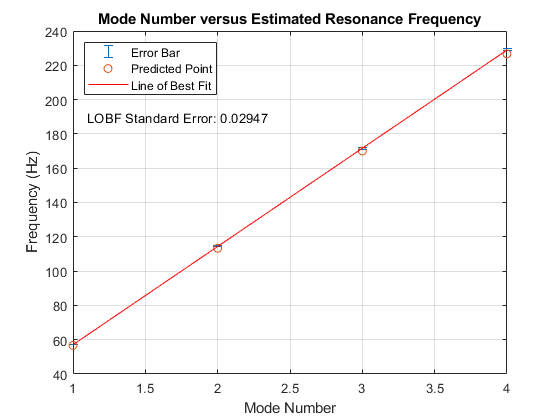


% Plot fit with data.
h = plot( fitresult );

xlabel("Mode Number");
ylabel("Frequency (Hz)");
legend("Error Bar", "Predicted Point", "Line of Best Fit", "Location", "NorthWest")
grid on 

text(1.1,190,"LOBF Standard Error: " + string(gof.sse))